# Third-Order One-Dimensional Hermitian Basis Functions

Computation of the third-order one-dimensional Hermitian basis functions, their first and second-order derivatives which are needed for the discretization of the Euler-Bernoulli beam formulation, namely,


$$\begin{array}{l}
N_1(\xi) = \frac{1}{4} \left( \xi - 1 \right)^2 \left( \xi + 2 \right) \\
N_2(\xi) = \frac{1}{8} \left( \xi - 1 \right)^2 \left( \xi + 1 \right) \\
N_3(\xi) =  - \frac{1}{4} \left( \xi + 1 \right)^2 \left( \xi - 2 \right) \\
N_4(\xi) = \frac{1}{8} \left( \xi - 1 \right) \left( \xi + 1 \right)^2
\end{array}$$


for $\xi \in \left[ -1, 1\right]$

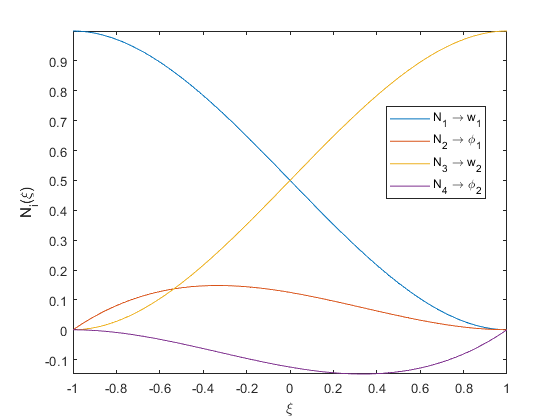

function dN = computeThirdOrderHermitianBasisFunctions1D(xi)

It computes the third-order one-dimensional Hermitian basis functions.

## Function description

            **Input** :

                 `xi` : Parametric coordinate in closed domain [-1, 1] 

        **Output** :

                `dN` : Array containing the third order Hermitian shape functions dN(:, 1), their first-order derivatives $\frac{\partial N_i (\xi) }{\partial \xi}$ stored in array `dN(:, 2)` and their second-order derivatives $\frac{\partial^2 N_i (\xi) }{\partial \xi^2}$ stored in array `dN(:, 3)`

## Function Implementation

### Input validation

arguments
    xi (1, 1) double {mustBeInRange(xi, -1, 1)}
end

### Read input and initialize output

    tol = eps;
    if xi < -1 - tol || xi > 1 + tol
        error("The provided parametric location xi = %f is outside the bounds [-1, 1]", xi);
    end
    dN = zeros(4, 3);

### Hermitian shape functions

$N_i(\xi)$ where $\xi \in \left[ -1, 1\right]$ and $i = 1,\ldots,4$

        dN(:, 1) = [ ((xi - 1)^2*(xi + 2))/4
                     ((xi - 1)^2*(xi + 1))/8
                    -((xi + 1)^2*(xi - 2))/4
                     ((xi - 1)*(xi + 1)^2)/8];

### First-order derivatives of the Hermitian shape functions


$$\frac{\partial N_i (\xi) }{\partial \xi}$$


        dN(:, 2) = [       (3*xi^2)/4 - 3/4
                    (3*xi^2)/8 - xi/4 - 1/8
                           3/4 - (3*xi^2)/4
                    (3*xi^2)/8 + xi/4 - 1/8];

### Second-order derivatives of the Hermitian shape functions


$$\frac{\partial^2 N_i (\xi) }{\partial \xi^2}$$


        dN(:, 3) = [      (3*xi)/2
                    (3*xi)/4 - 1/4
                         -(3*xi)/2
                    (3*xi)/4 + 1/4];

end